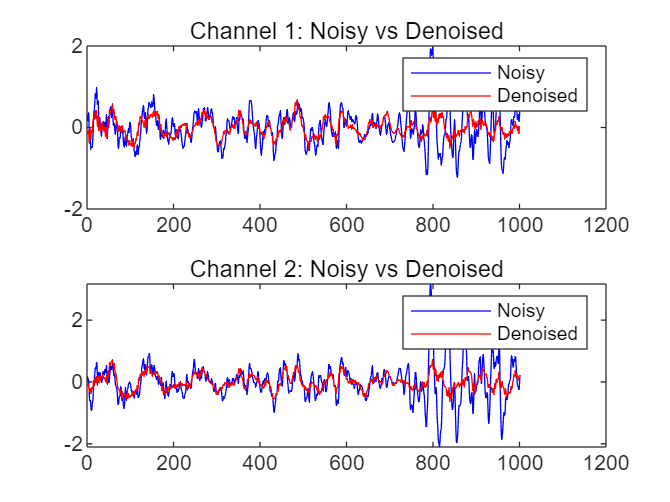

%% 还可以
%% NLMS-Based Adaptive Noise Cancellation for Stereo Audio
clear; close all; clc;

%% === 1. Load Data ===
load('Hw2a.mat');  % loads Sin_a, Sn_ref_a, fs
[N, M] = size(Sin_a);  % N: samples, M: stereo channels

%% === 2. Parameters ===
filter_order = 128;   % FIR filter length
mu = 0.01;            % normalized step size (0 < mu < 2)
delta = 1e-6;        % small constant to avoid divide-by-zero
max_samples = N;     % or for test: min(20000, N)

%% === 3. Initialization ===
Sin_est = zeros(N, M);        % output estimated signal
W = zeros(filter_order, M);   % NLMS filter weights

%% === 4. NLMS Adaptive Filtering ===
for ch = 1:M
    x = Sn_ref_a(1:max_samples, ch);  % reference noise
    d = Sin_a(1:max_samples, ch);     % noisy speech
    y = zeros(max_samples, 1);        % filter output
    e = zeros(max_samples, 1);        % error (estimated clean)

    for n = filter_order:max_samples
        x_n = x(n:-1:n-filter_order+1);             % current input window
        y(n) = W(:,ch)' * x_n;                      % predicted noise
        e(n) = d(n) - y(n);                         % residual (speech)
        norm_x = x_n' * x_n;                        % input power
        W(:,ch) = W(:,ch) + (mu * e(n) * x_n) / (norm_x + delta);  % NLMS update
    end

    Sin_est(1:max_samples, ch) = e;  % store output
end



%% === 6. Time Domain Visualization ===
figure;
for ch = 1:M
    subplot(M, 1, ch);
    plot(Sin_a(N-111000:N-110000, ch), 'b'); hold on;
    plot(Sin_est(N-111000:N-110000, ch), 'r');
    title(['Channel ', num2str(ch), ': Noisy vs Denoised']);
    legend('Noisy','Denoised');
end

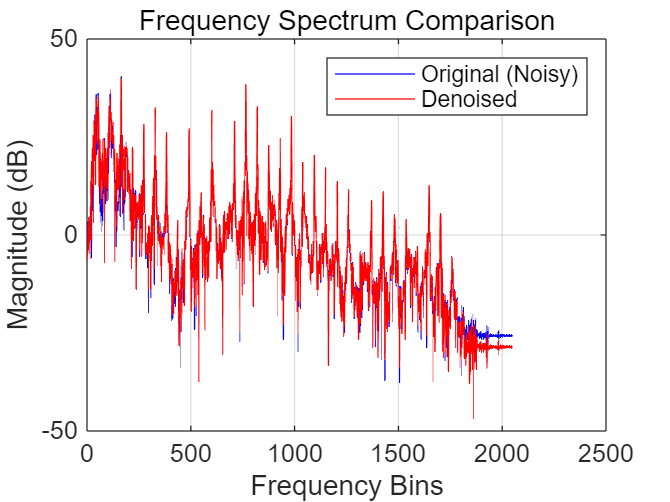


%% === 7. Frequency Domain Comparison ===
N_fft = 4096;
S = fft(Sin_a(:,1), N_fft);
E = fft(Sin_est(:,1), N_fft);

figure;
plot(20*log10(abs(S(1:N_fft/2))), 'b'); hold on;
plot(20*log10(abs(E(1:N_fft/2))), 'r');
legend('Original (Noisy)', 'Denoised');
title('Frequency Spectrum Comparison');
xlabel('Frequency Bins');
ylabel('Magnitude (dB)');
grid on;


%% === 5. Listen to Results ===
disp('▶ Playing denoised audio...');

▶ Playing denoised audio...


sound(Sin_est(:,1:M), fs);
pause(max_samples / fs + 1);
